# EE105 Simulinjk Lab: Block DIagram SImulation as an Engineer;s Problem Solving Tool

# Name: Buddy Ugwumba SID: 862063029

## Abstract

- This lab is an introduction to block diagram simulation; specifically Simulink extension of Matlab.

-  Future assignments will require Simulink

## Prelab

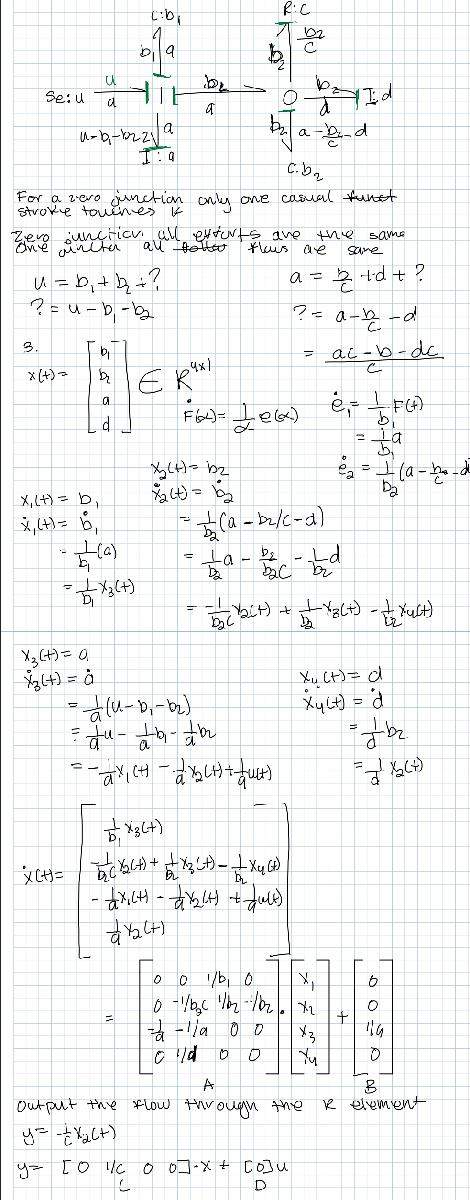

2.1 (5'')

% Output: The flow through the R-element
% Define the value for a,b,c,d and matrix A
a = 1;
b = 9;
c = 0.1;
d = 1;
A = [ 0 0 1/b 0; 0 -1/(b*c) 1/b -1/b; -1/a -1/a 0 0; 0 1/d 0 0];
% eig(A) Helps us find the poles of the system
eig(A)

ans =   -0.8727 + 0.0000i
  -0.0556 + 0.3287i
  -0.0556 - 0.3287i
  -0.1273 + 0.0000i


2.2

The formula can be found in the LectureNotes.

Dominant time constant: (3'')

% tau = 1/a where a is the dominant pole
tau = 1/0.0556

tau = 17.9856

Time to decay away: (2'')

% T_s = ?
T_S = 4.6/(0.0556)

T_S = 82.7338

2.3

Create the Simulink model, name it as 'sec2_3'.

**Simulink setting requirement:  (5'')**

- **Stop time: 300s**

- **Max step size: 0.01**

- **Unit sinusoidal input: Amplitude = 1, Frequency = 1 rad/s**

- **In your Simulink model, do not input the specified value for 'Gain', you can just use the variable expression. like '1/c', '1/b' and so on. Before running the Simulink, you should run your live script first, to get the variables into the workspace.**

Your Simulink model: (5'')

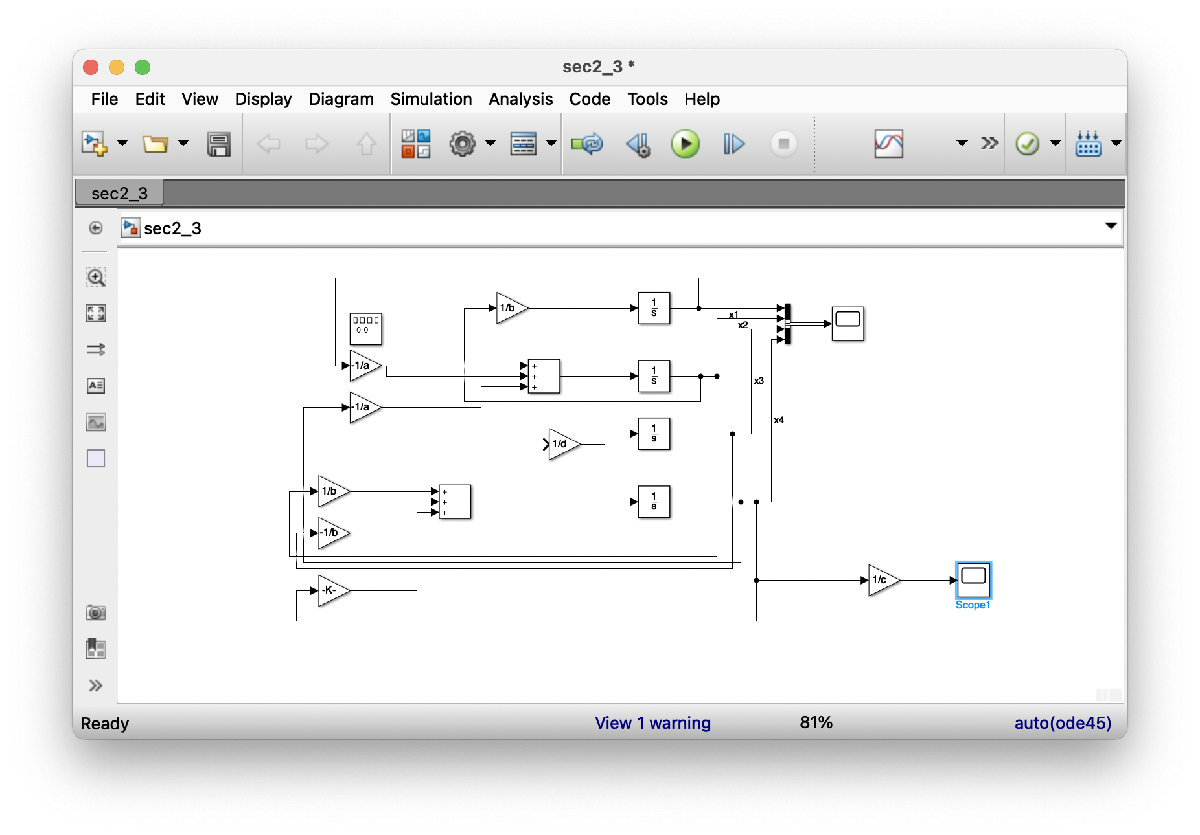

Show the simulation result for output y: (10'')

(You result should be similar to the figure below:)

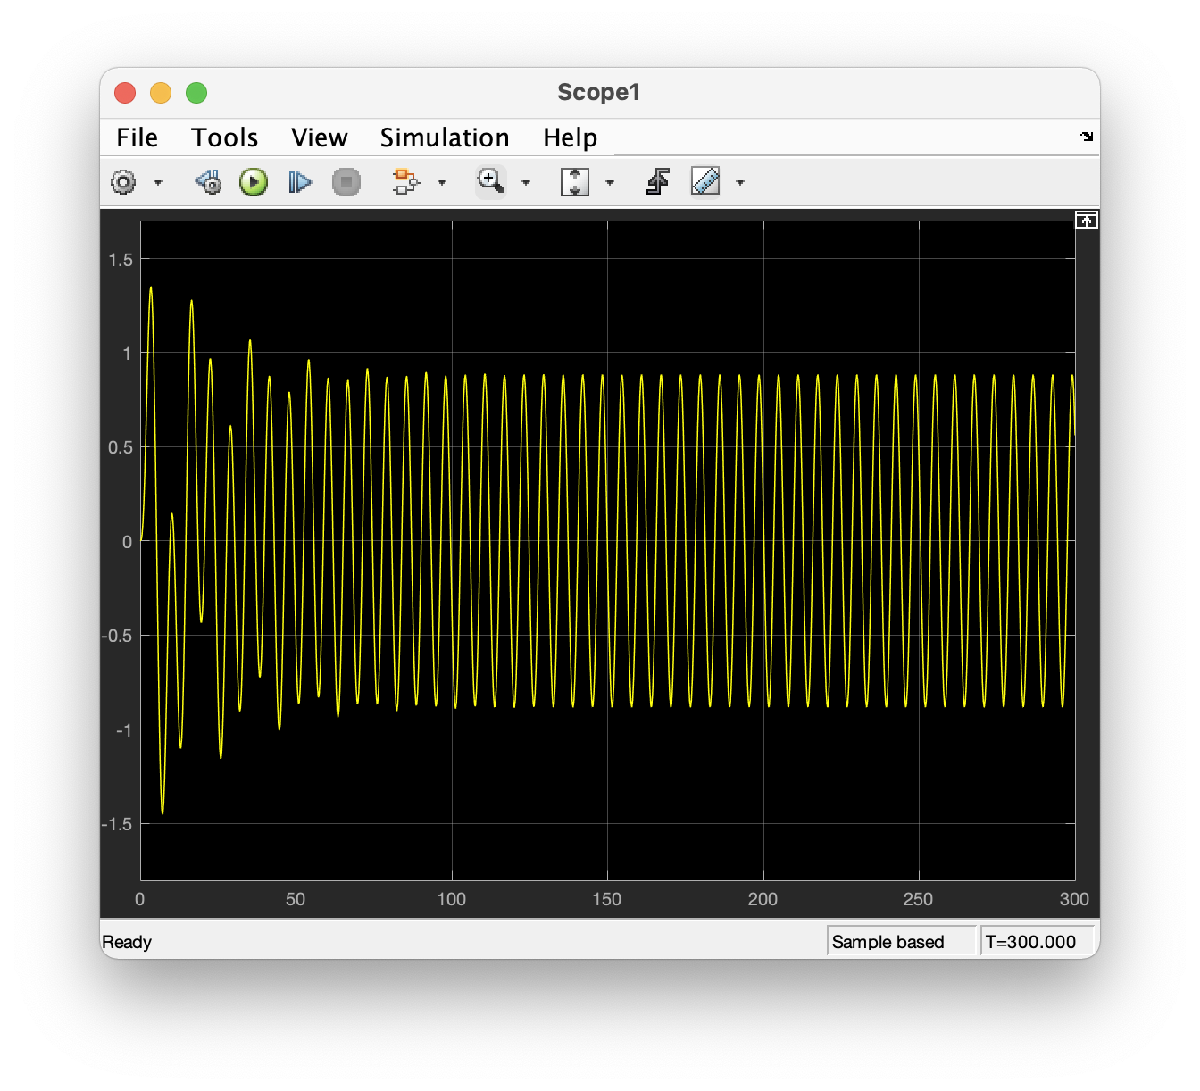

2.3 (b)

Try frequencies: 10e-3, 0.01, 0.05, 0.2, 0.27, 1/3, 0.58, 1, 5, 20, 50 rad/s

Record the amplitude of the steady-state using cusor measurement.

Plot the amplitude of the steady-state output versus the radian frequency of the input using a loglog scale. (5'')

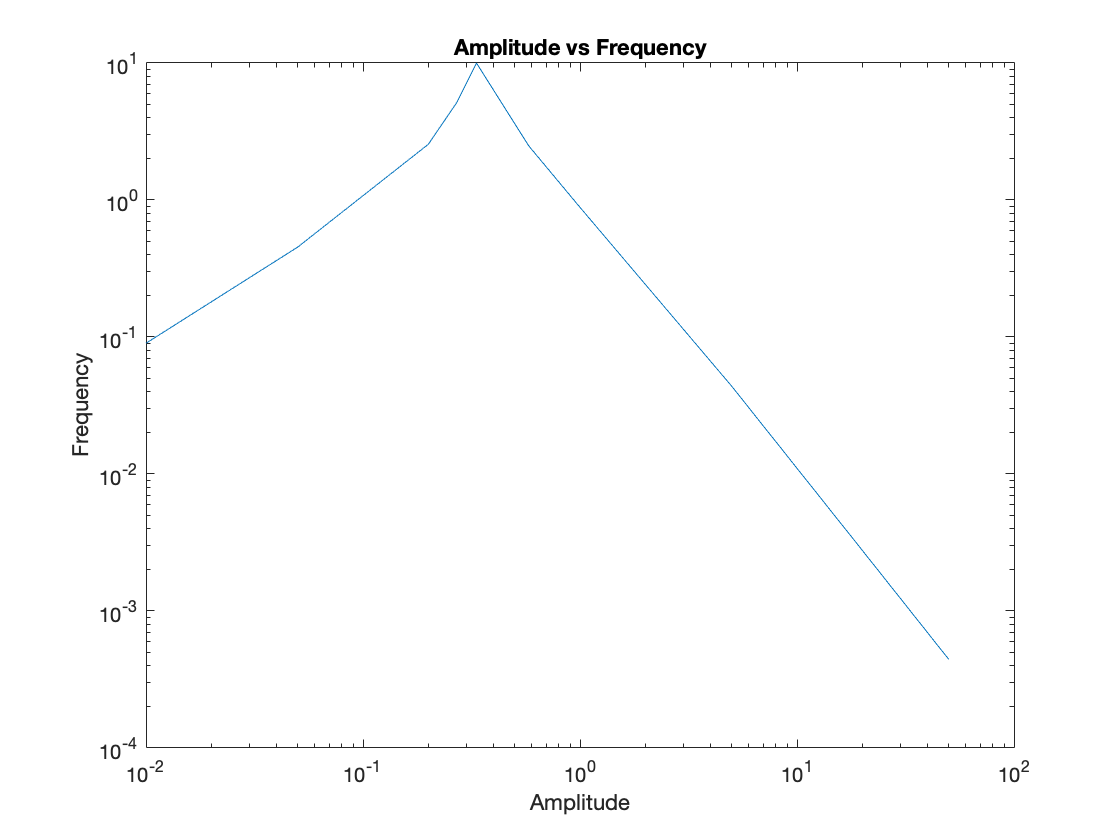

f = [10e-3, 0.01, 0.05, 0.2, 0.27, 1/3, 0.58, 1, 5, 20, 50];
amp = [9.005e-02 9.006e-02 4.531e-01 2.552e+00 5.124e+00 9.997e+00 2.489e+00 8.838e-01 4.376e-02 2.77e-03 4.443e-04];
% plot amp versus f
loglog(f,amp)
% xlabel, ylabel, title
xlabel('Amplitude')
ylabel('Frequency')
title('Amplitude vs Frequency')

Is there a frequency at which the output magnitude is maximum? (3'')

2.3 (c) Answer Yes or No. (2'')

Yes, there is a frequency at which the output magnitude is maximum. That frequency is 9.997

2.4  (50'' total)

(a) (6'')

% A has been defined in 2.1
% B = ?; C=?; D=?;
B = [0; 0; 1/a; 0];
C = [0 1/c 0 0];
D = 0;

(c) Since d has been defined before, using a differen variable (4'')

% [num,den]=ss2tf(A,B,C,D)
[num,den]=ss2tf(A,B,C,D)

num =          0         0    1.1111    0.0000   -0.0000


den =     1.0000    1.1111    0.3333    0.1235    0.0123


(d) (10'')

% Ploes?
roots(num)

ans = 	1.0e+-8 *

   -0.2953
    0.2953


% Zeros?
roots(den)

ans =   -0.8727 + 0.0000i
  -0.0556 + 0.3287i
  -0.0556 - 0.3287i
  -0.1273 + 0.0000i


(e) 

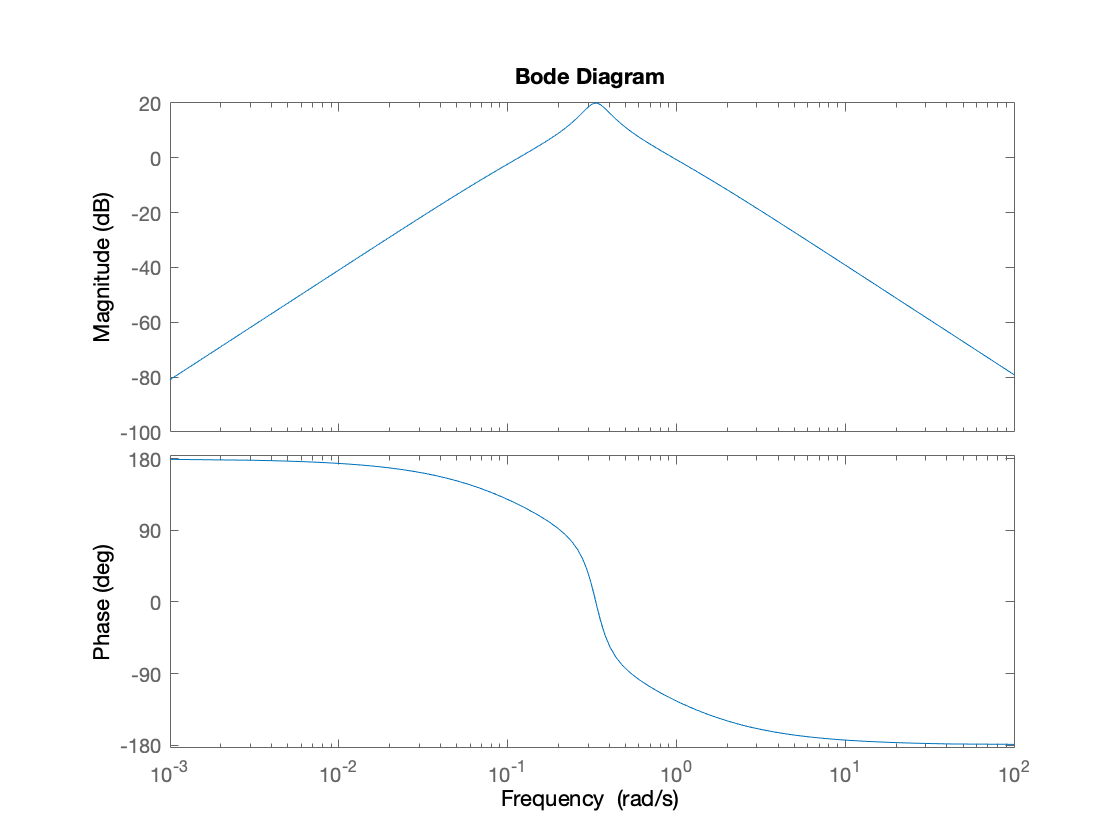

% bode(num,den) (5'')
bode(num,den)

What will be the amplification for maximizing the gain? (5'')

The amplificiation for maximizing the gain is a frequency of 0.335 to get a gain of 19.94

2.4 Simulink:

Create the Simulink model, name it as 'sec2_4'.

**Simulink setting requirement for Stop time and Max step size same as what in 2.3**

Notice that the input signal requency should be the one you get from the last step.

(h)

Your model: (5'')

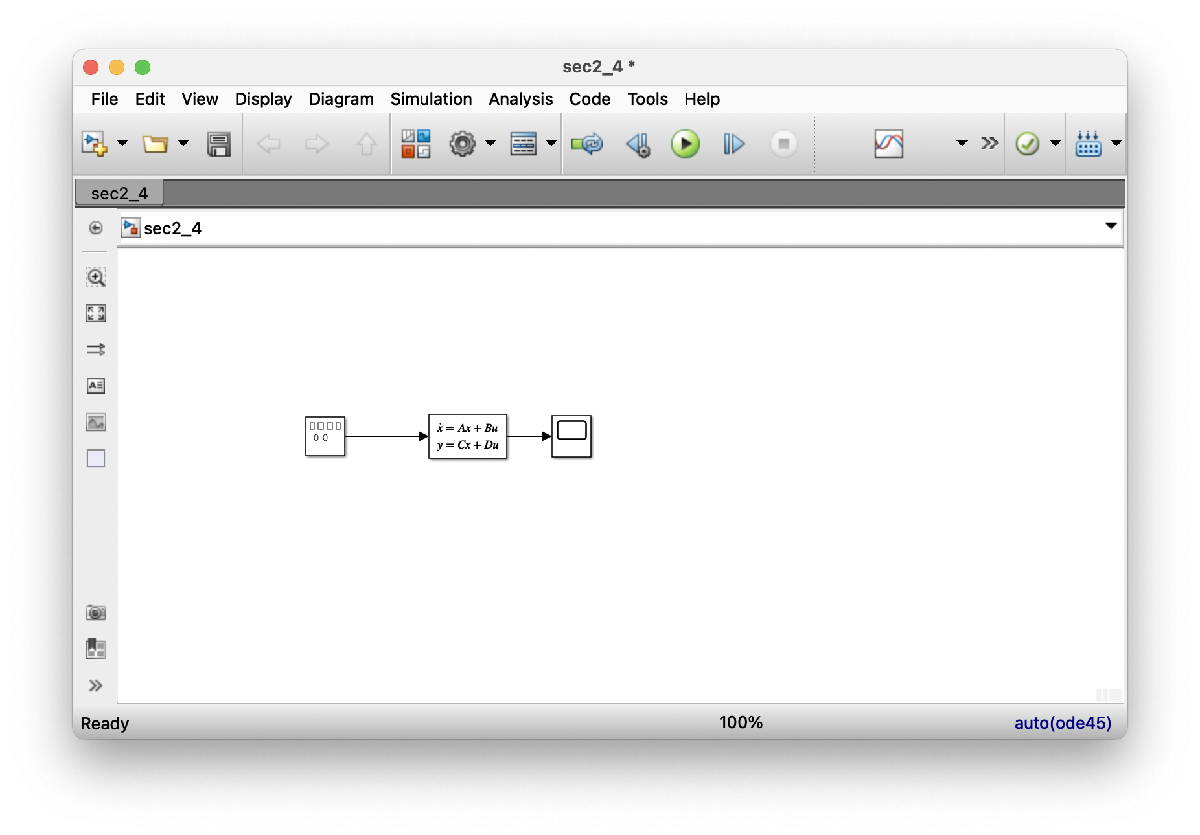

(i)

Show the simulation result for output y: (10'')

(You result should be similar to the figure below:)

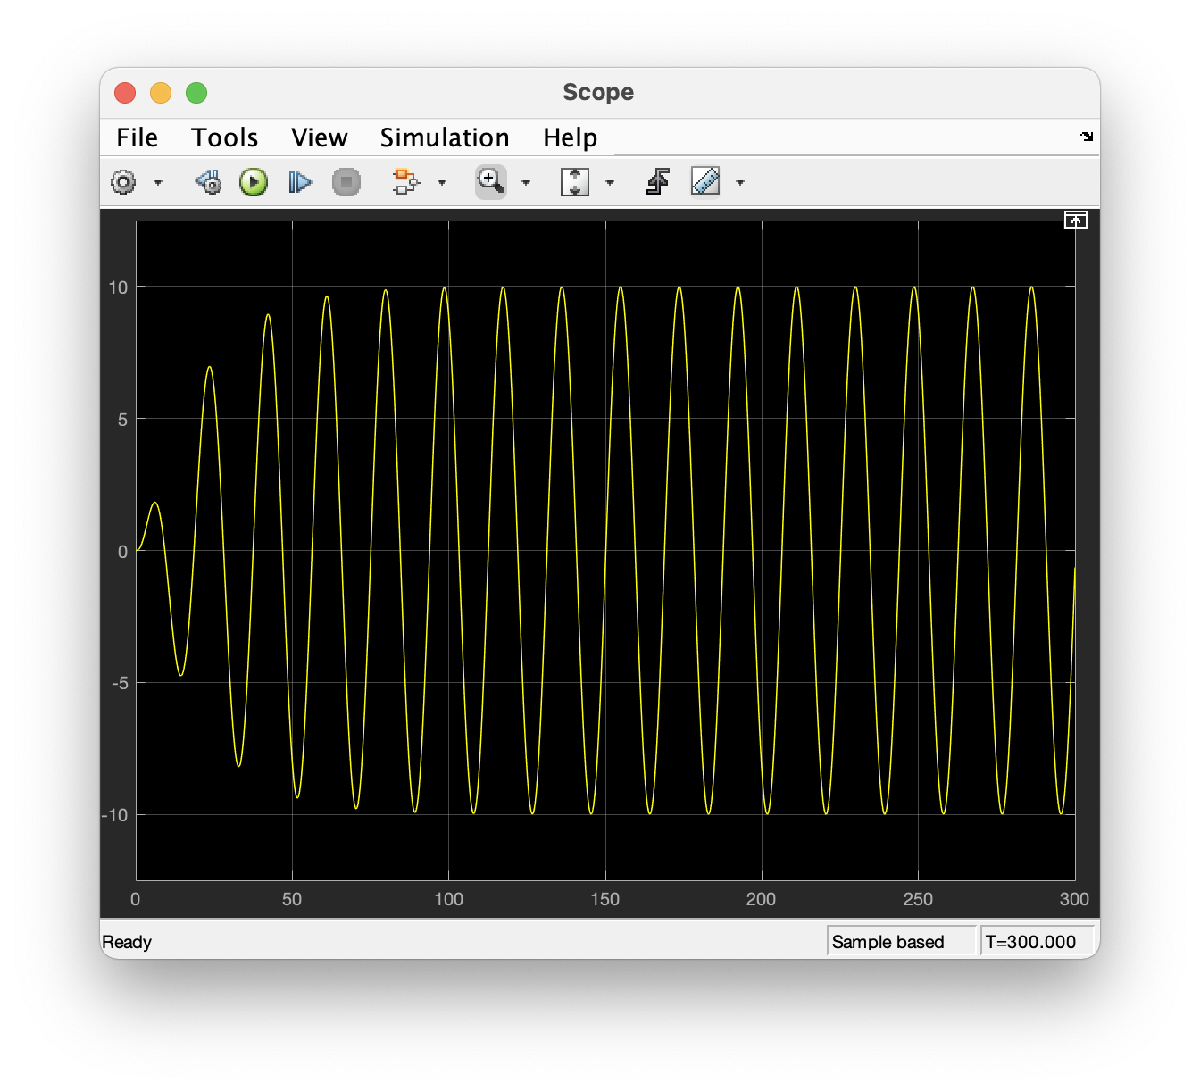

(j) (5'')

Using the cursor measurement measure the gain. Then compare it with the Bode plot.

mag2db(9.957e+00)

ans = 19.9626

Thus the value matches the one I got in the previous section. 